% Lab 4 – Task 1b: testing the gyroscope
clear all
close('all')
ports = serialportlist;
pb = PyBench(ports(end));  % create a PyBench object

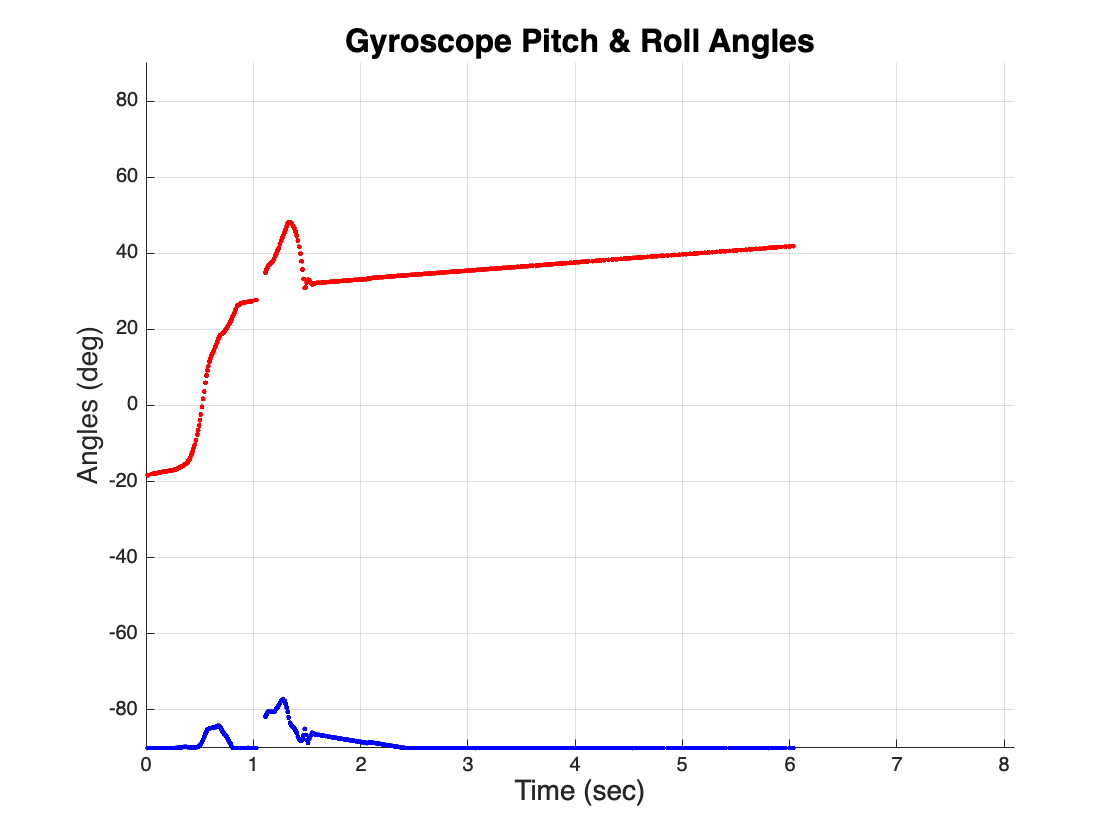

N = 500;  % each graph is 500 time points
end_time = 10.0;  % initial guess of time axis range
gx = 0; gy = 0; % initialise angles gy pitch, gx roll

while true
    % Plot the axes first for plot later
    figure(1)
    clf(1)
    axis([0 end_time -90 90]);
    title('Gyroscope Pitch & Roll Angles','FontSize', 16);
    ylabel('Angles (deg)','FontSize', 14);
    xlabel('Time (sec)','FontSize', 14);
    grid on; hold on;
    timestamp = 0;
    tic;
    
    % read gyroscope data
    for i = 1:N
        [x, y, z] = pb.get_gyro();  % angular rate in rad/sec
        dt = toc;  % get elapsed time
        tic;
        timestamp = timestamp + dt;
        gx = max(min(gx + x * dt, pi/2), -pi/2);  % limit to +/- pi/2
        gy = max(min(gy + y * dt, pi/2), -pi/2);
        plot(timestamp, gy * 180 / pi, '.b');  % plot pitch in blue
        plot(timestamp, gx * 180 / pi, '.r');  % plot roll in red
        pause(0.001);  % delay for 1 ms, needed for plot
    end  % for loop
    end_time = timestamp;  % use actual time range from now on
end  % while